# Azionamento - Motore in Corrente Continua

## Scopo del progetto

Lo scopo del progetto è quello di progettare un azionamento in **motore in corrente continua spazzolato** per un'applicazione a scelta dello studente. In particolare si adopererà la tecnica del **controllo d'armatura**.

Note di lettura:

- Laddove non specificata l'unità di misura vicino la variabile, si considera la misura standard del SI senza fattori pre-moltiplicativi (es lunghezza -> m, massa -> kg, tempo ->s ecc..)

- I plot verranno generati e opportunamente salvati in una cartella locale: **plot_folder**

%se non esite la cartella verrà creata
plot_folder = fullfile('..', 'Immagini', 'PlotMatlab'); % path ..\Immagini\PlotMatlab
if ~exist(plot_folder, 'dir')
    mkdir(plot_folder);
end


## Applicazione d'interesse e specifiche primarie

Si vuole progettare un azionamento per lo scorrimento di un **tapis roulant**.

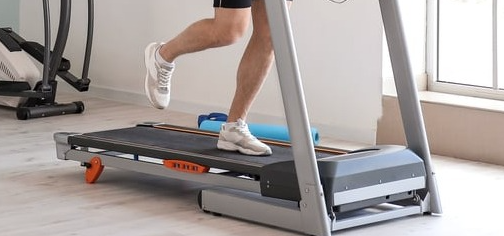

Per le specifiche primarie si consideri un modello di tapis roulant di fascia medio-alta: 

- Velocità regolabile da 0 a 18km/h

- Raggiungimento velocità desiderata in tempo massimo di 8s

- Portata massima: 170kg 

%specifiche primarie
v_tapis_max_kmh =  18

v_tapis_max_kmh = 18

delta_t_acc_max = 8     %tempo per raggiungere v max

delta_t_acc_max = 8

portata_max = 170

portata_max = 170

## Struttura meccanica

Si prenda in considerazione una struttura meccanica descritta dal seguente cad

[conveyor belt | 3D CAD Model Library | GrabCAD](https://grabcad.com/library/conveyor-belt-123)

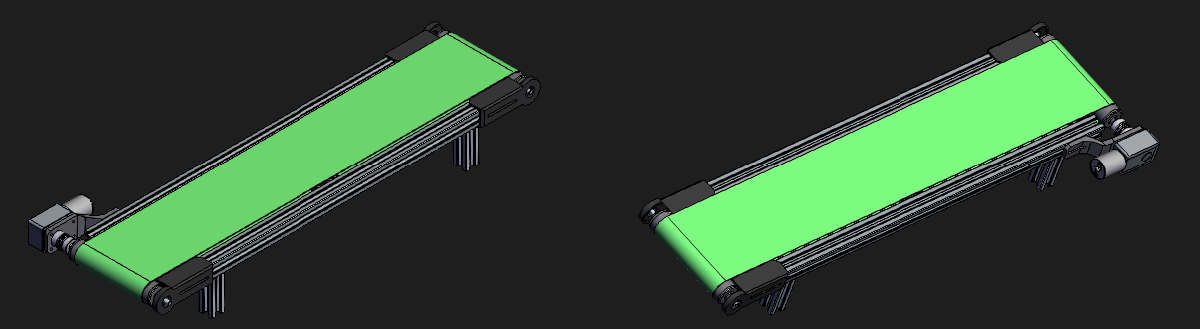

La struttura è composta da:

- x2 rulli identici di cui uno motorizzato e uno inerte

- tappeto che scorre ancorato ai rulli

- x1 motore in corrente continua spazzolato, sensorizzato

- (+ cuscinetti per garantire uno scorrimento favorevole del tappeto)

le cui misure sono le seguenti

- tappeto: 120cmx50cm

- peso tappeto: 5kg

- rullo: diametro 5cm

- peso per rullo: 6kg

dalle quali è possibile ricavare i momenti d'inerzia*

%misure
m_tappeto = 5;
m_rullo = 6;
r_rotazionale = 0.05 / 2;

%momenti d'inerzia
J_rullo = 1/2 * m_rullo * r_rotazionale^2;
J_tappeto = m_tappeto * r_rotazionale^2;

J_macchina = 2*J_rullo + J_tappeto

J_macchina = 0.0069

*si considera per il tappeto l'equivalente rotazionale, pur essendo un elemento traslatorio -> J = m*r dove r è il raggio rispetto a cui ruota, ovvero quello del rullo

## Scelta motore

Il settore applicativo ci preannuncia che avremo bisogno di un motore da almeno 1kW. Ipotizziamolo. In seguito verificheremo che il motore sia sufficiente.

Scegliamo il seguente motore.

[MOTORE ELETTRICO 24Vdc 1000W 3000Rpm - L80B14 - Elip Tagliente Shop](https://www.shop.eliptagliente.it/prodotto/motore-elettrico-24vdc-1000w-3000rpm-l80b14/)

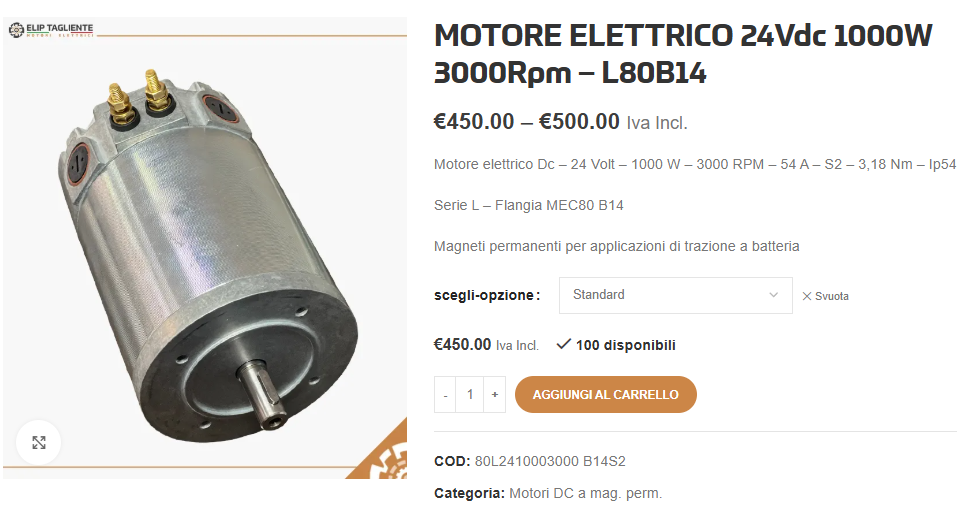

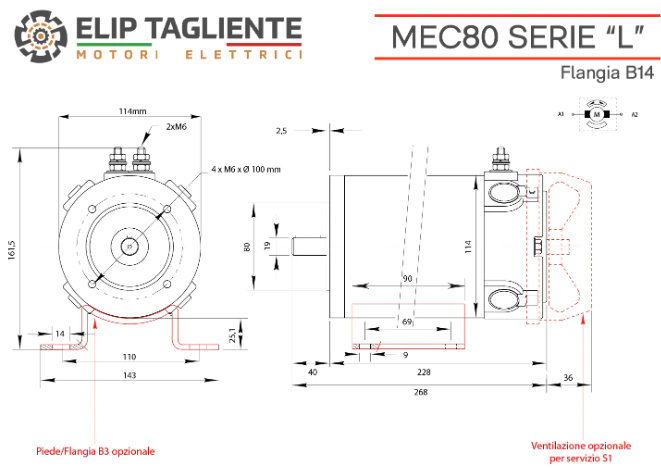

Nota: Sul sito indicato sono indicate le sue principali applicazioni e si può constatare che una di queste è proprio l'impiego per tapis roulant.

Si possono estrarre le seguenti utili caratteristiche (**DATI DI TARGA**)

- Tensione nominale: 24V

- Corrente nominale: 54A

- Potenza nominale: 1000W (meccanica)

- Velocità nominale: 3000 RPM -> 314 rad/s

- Coppia nominale: 3.18 Nm

- Peso: 6.15Kg

- Diametro rotore: 11cm

e ricavarne altre

%DATI DI TARGA
Va = 24;
Ia = 54;
Pa_mecc = 1000;                                         %potenza meccanica nominale
wa_motore_rad_s = 314

wa_motore_rad_s = 314

Ca = 3.18;
m_motore = 6.15;
diametro_motore = 0.11;

%DATI RICAVATI
Pa_elett = Va * Ia                                      %potenza elettrica nominale

Pa_elett = 1296

J_motore = 1/2 * m_motore * (diametro_motore/2)^2       %inerzia del motore

J_motore = 0.0093

Nota: abbiamo bisogno in questo progetto di scegliere il motore prima delle specifiche, perché abbiamo bisogno di alcune sue caratteristiche (come la sua inerzia) nella definizione delle stesse.

## Specifiche in potenza dell'applicazione

Dalle specifiche primarie è possibile ricavarsi specifiche tecniche per la scelta del motore

- velocità rotazionale massima, necessaria

- coppia massima, necessaria

- potenza necessaria

Dalle specifiche sulla velocità e la struttura dei rulli

w_max_rad_s = (v_tapis_max_kmh / 3.6) /r_rotazionale     %da v=wr

w_max_rad_s = 200

Dalle specifiche sull'accelerazione. 

So che devo raggiungere la velocità massima in un tempo prestabilito e farlo con un carico di portata p. Usiamo a tal scopo una massa campione di 1,25p che sale sul tappeto. Questo porta due vantaggi significativi:

- ci dà un margine di robustezza ulteriore oltre a quella ottenuta dal sovradimensionamento in potenza del motore

- modella i picchi di massa "percepita" durante la corsa sul tappeto, in particolare nell'urto durante la fase di atterraggio del piede

%effetto di carico
sovradimensionamento_carico = 1.25;
massa_carico_max = sovradimensionamento_carico * portata_max;
J_massa_carico_max = massa_carico_max * r_rotazionale^2

J_massa_carico_max = 0.1328



%inerzia tot e accelerazione da imprimergli
J_tot = J_macchina + J_motore + J_massa_carico_max

J_tot = 0.1490

alpha_max = w_max_rad_s / delta_t_acc_max

alpha_max = 25


C_max = J_tot * alpha_max

C_max = 3.7247

Nota: così come il nastro, il carico (la persona) è un'inerzia traslatoria. Ne è stata considerata l'inerzia rotazionale equivalente J = mr^2

A questo punto possiamo calcolare la potenza richiesta 

%Potenza richiesta al motore
P_richiesta = C_max * w_max_rad_s

P_richiesta = 744.9469

### Considerazioni su motore e verifica della compatibilità; introduzione del riduttore

Pur considerando un 10% di perdite meccaniche, l**a potenza del motore scelto è sufficiente** per la nostra applicazione

perc_perdite_meccaniche = 0.1;
P_perdite_mecc = Pa_mecc * perc_perdite_meccaniche

P_perdite_mecc = 100

Pa_mecc_effettivo = Pa_mecc - P_perdite_mecc

Pa_mecc_effettivo = 900

Notiamo in realtà che la coppia massima non è soddisfatta dalla coppia nominale del motore, mentre la velocità raggiungibile è decisamente superflua.

Scegliamo così di usare un **riduttore **con rapporto di trasformazione R_rid, scelto in modo tale da avere wa = wmax

%desiderato
R_rid = wa_motore_rad_s / w_max_rad_s

R_rid = 1.5700

Scegliamo il seguente riduttore, che ha un rapporto compatibile

[Riduttori a ingranaggi cilindrici R | SEW-EURODRIVE](https://www.sew-eurodrive.it/prodotti/riduttori/riduttori_standard/riduttori_ad_ingranaggi_r/riduttori_ad_ingranaggi_r.html) ad uno stadio

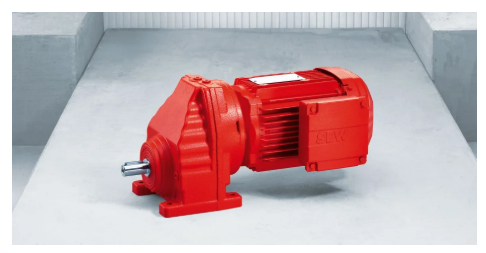

NOTA: il riduttore generalmente ha un'inerzia dell'ordine del 10^(-3) o 10^/(-4) che è così bassa da essere trascurata nel nostro caso.

Col rapporto di riduzione, supposto ideale il riduttore (ovvero non ho una perdita di efficacia), le grandezze del motore diventano

fprintf("nominali a valle del riduttore:");

nominali a valle del riduttore:

wa_motore_riduttore_rad_s = wa_motore_rad_s / R_rid

wa_motore_riduttore_rad_s = 200

Ca_riduttore = Ca * R_rid

Ca_riduttore = 4.9926


fprintf("dove le richieste erano:");

dove le richieste erano:

w_max_rad_s

w_max_rad_s = 200

C_max

C_max = 3.7247

Quindi ho coperto le specifiche necessarie

## Modello del motore e parametrizzazione

dalle equazioni del controllo d'armatura

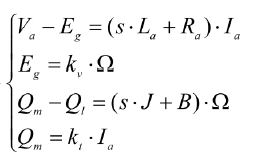

lo schema a blocchi del motore è il seguente

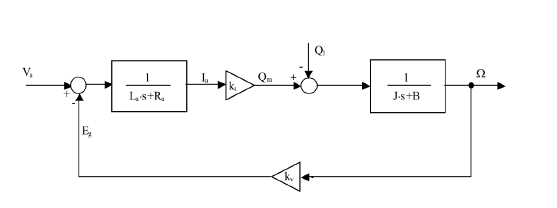

Abbiamo bisogno di altri suoi parametri caratteristici che possiamo ricavare e stimare.

- Ra - resistenza d'armatura

- La - induttanza d'armatura

- B - coeff attrito viscoso

- Costanti macchina kv e kt

La resistenza d'armatura si può calcolare dalle perdite elettriche

P_perdite_elett = Pa_elett - Pa_mecc

P_perdite_elett = 296

Ra = P_perdite_elett / Ia^2

Ra = 0.1015

L'induttanza d'armatura non possiamo calcolarla dalle specifiche, avremmo bisogno di fare delle prove sul motore. Pertanto, scegliamo un valore classico per questo tipo di motori.

La = 1*10^(-4)

La = 1.0000e-04

Il coeff. attrito viscoso può essere calcolato dalle perdite meccaniche (stimate prima al 10%)

Beta = P_perdite_mecc / wa_motore_rad_s^2

Beta = 0.0010

Il coefficiente kt può essere trovato dalla relazione tra coppia e corrente nominale

kt = Ca / Ia

kt = 0.0589

Il coefficiente kv può essere stimato sulle prove del motore a vuoto, che portano al seguente calcolo in forma chiusa

kv = (Va - Ra * wa_motore_rad_s * Beta / kt) / wa_motore_rad_s

kv = 0.0747

**Nota importante: inerzia motore**

Come J usiamo Jmacchina+Jmotore in quanto Jmacchina è una componente fissa di cui tener conto, non avrebbe senso modellarla esternamente.

Invece le variazioni di inerzia (dovute a persone che salgono sul tapis ed altro), saranno modellate in Ql, coppia di carico.

## Schema a blocchi del motore, implementazione

Lo schema a blocchi è stato implementato nel seguente schema simulink

[./motore.slx](matlab:open('./motore.slx'))

Per verificarne la correttezza, lanciamo la simulazione ad un ingresso a gradino ad 1s, di ampiezza tensione nominale Va con carico a vuoto (Ql = 0)

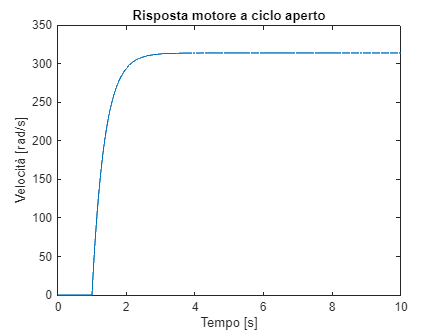

%simulazione
model = 'motore';
load_system(model);
Tsim = 10;  % Durata della simulazione
set_param(model, 'StopTime', num2str(Tsim));
out = sim(model);

%grafico i risultati della simulazione
figure;
plot(out.w_sim)
title("Risposta motore a ciclo aperto")
xlabel('Tempo [s]');
ylabel("Velocità [rad/s]");

filename = fullfile(plot_folder, 'rispostaMotoreCicloAperto.png');
saveas(gcf, filename);


regime = out.w_sim.Data(end)    %velocità a cui si è portato

regime = 314.0001

Il motore converge a velocità nominale, che è coerente con la modellistica.

### Blocchi aggiuntivi - amplificatore, dinamo tachimetrica, clamping in corrente

#### Amplificatore

Immaginiamo di impiegare per il controllo un **microcontrollore**, che può generare tensioni tra 0 e 5V. Avremo bisogno di un **amplificatore** con guadagno Va/High per arrivare alle tensioni del motore.

Gnd = 0;
High_voltage = 5;

kamp = Va/ High_voltage

kamp = 4.8000

#### Dinamo tachimetrica

Per la catena di retroazione, per misurare la velocità, utilizziamo una **dinamo tachimetrica**

[Cat_DT1.pdf](https://hohner.it/datasheet/itaing/vari/Cat_DT1.pdf?x18985)

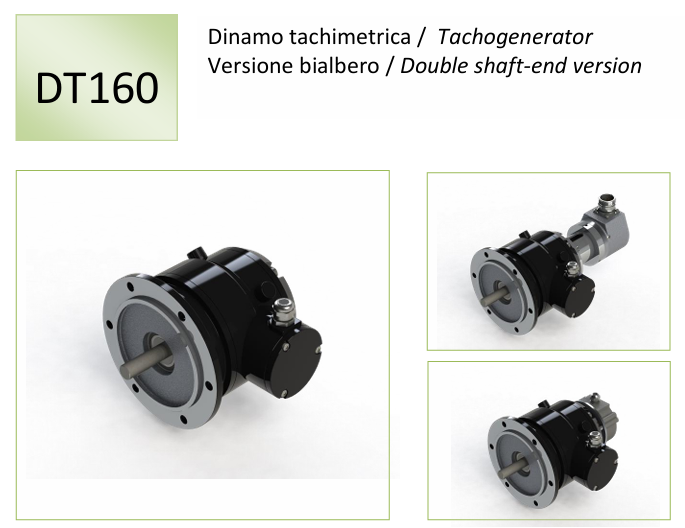

Si possono estrarre le seguenti utili caratteristiche (**DATI DI TARGA**)

- Tensione d'uscita a velocità fissata: 60V a 1000RPM

- Numero lamelle: 33

- Peak-to-Peak massimo: 1% dell'output

Per la dinamo non ideale modelleremo il **rumore** con la sua armonica fondamentale, che ha frequenza Nlamelle volte w e un'ampiezza pari al ripple di tensione.

Inoltre, ricordiamo che l'uscita della dinamo dev'essere compatibile con il riferimento generato dal micro, dunque si deve rimappare il segnale su un range di [Gnd, High_Voltage] e useremo un deamplificatore.

%dati sul rumore di misura
Nlamelle = 33

Nlamelle = 33

AmpiezzaRumorePercentuale = 0.01

AmpiezzaRumorePercentuale = 0.0100



%costante tachimetrica
wa_din = 1000/(60*2*pi);
Va_din = 60;

kdt = Va_din/wa_din 

kdt = 22.6195

k_deamp = High_voltage / (wa_motore_rad_s * kdt)

k_deamp = 7.0398e-04

Sceglieremo durante il progetto di fare simulazioni con una dinamo ideale o reale. Per rendere tutto automatizzato, useremo una variabile booleana "*noise_on*"

- True = dinamo reale

- False = dinamo ideale

In simulink il modello della dinamo è il seguente

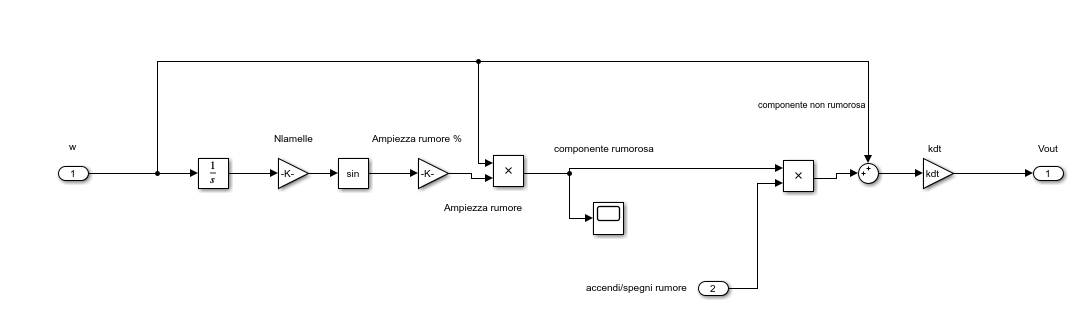

NOTA: la dinamo ha una sua inerzia trascurabile rispetto al totale, dunque la trascuriamo

#### Saturatore clamping

Introduciamo un circuito **saturatore clamping** in corrente per non avere correnti troppo elevate in picco, soprattutto in fasi di discontinuità di funzionamento, come l'accensione del motore. Useremo un blocco deadzone e una compensazione: k_compenso *  corrente_in_eccesso

DeadZoneCorrente  = Ia

DeadZoneCorrente = 54

k_compenso = 100

k_compenso = 100

k_compenso è stato trovato con **taratura** **manuale** monitorando la corrente a tensione d'ingresso massima, finché non è risultata completamente satura attorno a Ia, usando regolatore proporzionale di guadagno 1 e supposto dinamo ideale.

#### SCHEMA RISULTANTE

Lo **schema senza il regolatore** risulta essere il seguente

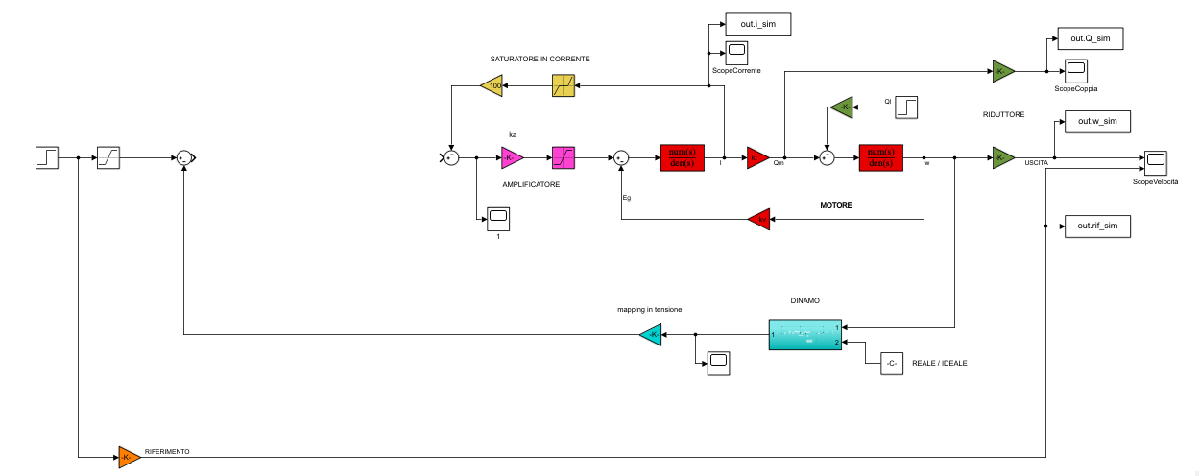 

### Simulazioni a ciclo chiuso e ingressi 

Si notifica il lettore che per il riferimento, è stato predisposto il seguente subsystem che può generare

- gradino

- rampa

- ingresso personalizzato da workspace

In questo codice useremo uno solo dei 3 ingressi alla volta.

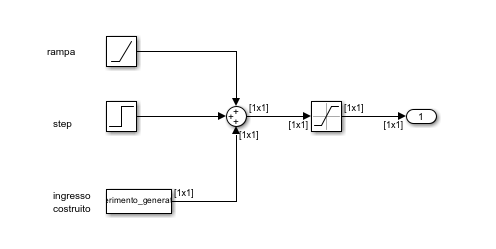

L'ingresso generato da workspace avrà un tempo di campionamento fisso

dt = 0.01;

Nota: per rendere il codice robusto, li setteremo con ridondanda ad ogni breakpoint.

### Regolatore PI

Faremo delle simulazioni (**taratura da campo**) per la cerca dei coefficienti usando lo schema simulink

[./controllo_motore.slx](matlab:open('./controllo_motore.slx'))

NOTA: In questa fase supporremo un **controllore non saturato e senza schema anti wind-up **(vedi prossimo breakpoint)

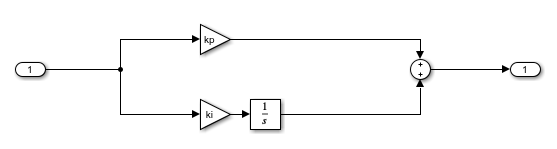

**Cerca di kp**

Spegniamo la parte integrativa.

Usando il modello di dinamo tachimetrica reale, che introduce il rumore che causa oscillazioni sulla corrente.

Faremo simulazioni finché non otteniamo:

- **ripple di corrente che è al sotto dell'1% di Ia **(specifica di progetto) 

- **corrente a livelli non oltre del 10% di Ia **(per pochi secondi)

Siccome vogliamo metterci nel caso peggiore, con la corrente più grande possibile, durante le simulazioni diamo in ingresso al motore l'ingresso massimo HighVoltage.

Quindi settiamo l'input simulink: un **gradino di ampiezza HighVoltage **e** dinamo reale**.

Tsim = 8;
set_input_sim(High_voltage, 0, genera_segnale_nullo(dt, Tsim), true, Inf, -Inf, false, 0, 0); 

Qui effettuiamo la ricerca

Ripple_Max = 0.5400

Ia_max = 59.4000

Iterazione 1: Kp = 625.00, Ripple = 21.3604, CorrenteMax = 85.2253 
Iterazione 2: Kp = 312.50, Ripple = 15.9333, CorrenteMax = 69.6087 
Iterazione 3: Kp = 156.25, Ripple = 7.9771, CorrenteMax = 61.7992 
Iterazione 4: Kp = 78.12, Ripple = 2.4262, CorrenteMax = 57.8942 
Iterazione 5: Kp = 39.06, Ripple = 15.5697, CorrenteMax = 55.9417 
Iterazione 6: Kp = 19.53, Ripple = 4.6056, CorrenteMax = 54.9654 
Iterazione 7: Kp = 9.77, Ripple = 4.7187, CorrenteMax = 54.4773 
Iterazione 8: Kp = 4.88, Ripple = 2.1915, CorrenteMax = 54.2332 
Iterazione 9: Kp = 2.44, Ripple = 1.0539, CorrenteMax = 54.1111 
Iterazione 10: Kp = 1.22, Ripple = 0.5224, CorrenteMax = 54.0501 


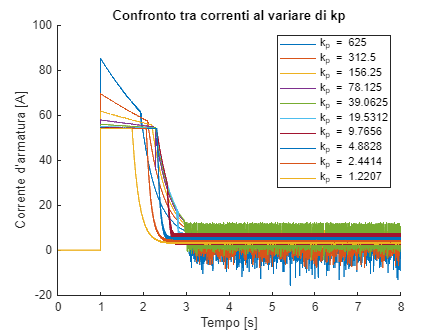

%imposto un flag per eseguire la ricerca di kp o non eseguirle per una
%volta che è stato già trovato
esegui_ricerca_flag = false;


if esegui_ricerca_flag 

    %specifiche desiderate
    Ripple_Max = 0.01 * Ia 
    Ia_max = 1.1 * Ia
    
    kp = 625;             % Valore iniziale di Kp
    ki = 0;               % Annullo parte integrativa
    
    kp_step = 2;          % Divido kp per kp_step
    max_iter = 20;        % Numero massimo di iterazioni
    iter = 0;
    
    
    % Inizializzazione array per salvare i risultati
    corrente_array = {}; 
    tempo_array = {};
    ki_array = {};
    
    
    % Inizializzazione
    ripple_corrente = Inf;
    max_corrente = Inf;
    
    
    % Inizio ciclo di ottimizzazione
    while (ripple_corrente > Ripple_Max || max_corrente >Ia_max) && iter < max_iter
        iter = iter + 1;
    
        % Simulazione
        out = run_simulation(Tsim);
    
         % Estrazione dei segnali
        corrente_array{iter} = out.i_sim.Data;
        tempo_array{iter} = out.i_sim.Time;
        kp_array{iter} = kp;
        
        
        %calcolo del picco
        max_corrente = max(corrente_array{iter});
    
        % Selezione dell'ultimo decimo della simulazione (elimino transitorio)
        indice_finale = tempo_array{iter} > Tsim * 0.9;
        corrente_finale = corrente_array{iter}(indice_finale);
        
        % Calcolo del ripple solo in quell'intervallo
        ripple_corrente = max(corrente_finale) - min(corrente_finale);
       
    
        % Stampa stato
        fprintf('Iterazione %d: Kp = %.2f, Ripple = %.4f, CorrenteMax = %.4f \n', iter, kp, ripple_corrente, max_corrente);
    
        % Aggiorno Kp
        if ripple_corrente > Ripple_Max || max_corrente >Ia_max
            kp = kp / kp_step;
        end
    end
    
    
    %plot del procedimento
    N = numel(corrente_array);  % Numero di plot
    
    figure;
    hold on
    for i = 1:N
        plot(tempo_array{i}, corrente_array{i}, 'DisplayName', ['k_p = ' num2str(kp_array{i})]);
    end
    xlabel('Tempo [s]');
    ylabel("Corrente d'armatura [A]");
    title('Confronto tra correnti al variare di kp');
    legend;
    hold off;

    filename = fullfile(plot_folder, 'confrontoCorrentiKp.png');
    saveas(gcf, filename);
    
else
    %kp già trovato da passate simulazioni
    kp = 1.22;
    ripple_corrente = 0.5224;
    max_corrente = 54.0501;
end




% Output finale
fprintf('\nValore finale di Kp: %.2f con Ripple = %.4f e corrente max = %.4f\n', kp, ripple_corrente, max_corrente);


Valore finale di Kp: 1.22 con Ripple = 0.5224 e corrente max = 54.0501


Tenendo spento ki e simulando il sistema, otteniamo i seguenti risultati

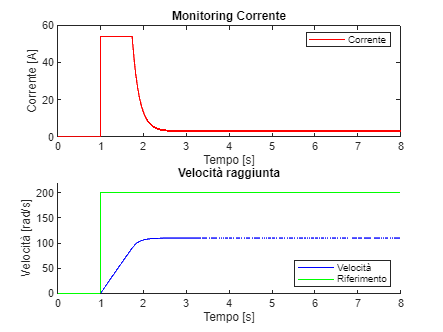

ki = 0;

%sim
out = run_simulation(Tsim);    

% Estrazione dei segnali
velocita = out.w_sim.Data;
tempo = out.w_sim.Time;
corrente = out.i_sim.Data;
riferimento = squeeze(out.rif_sim.Data);


% Plot dei risultati
figure;

subplot(2, 1, 1);
plot(tempo, corrente, 'r', 'DisplayName', 'Corrente');
title('Monitoring Corrente');
xlabel('Tempo [s]');
ylabel('Corrente [A]');
legend;

subplot(2, 1, 2);
hold on;
plot(tempo, velocita, 'b', 'DisplayName', 'Velocità');
plot(tempo, riferimento, 'g', 'DisplayName', 'Riferimento');
title('Velocità raggiunta');
xlabel('Tempo [s]');
ylabel('Velocità [rad/s]');
ylim([0 riferimento(end)*1.1])
legend('Location', 'southeast');
hold off;


filename = fullfile(plot_folder, 'controlloSoloProporzionale.png');
saveas(gcf, filename);

- La corrente **non supera i limiti massimi**, saturando e ha un **ripple a regime molto piccolo**

- Il motore a regime **segue il riferimento in velocità con un errore costante (ma significativo)**

Per superare il limite dell'errore dell'inseguimento a gradino, dobbiamo introdurre la parte integrativa, termine 1/s che ne garantisce l'astatismo.

**Cerca di Ki**

Studiamo la risposta a gradino del sistema al variare di Ki.  Vogliamo:

-  **sovraelongazione% della riposta a gradino in velocità, del massimo 20%**.

Stavolta diamo in ingresso un piccolo step, preoccupandoci che non mandi in saturazione il sistema.

Non avendo problemi sul disturbo con la parte integrativa e avendo già tarato appositamente la parte proporzionale, userò il modello di dinamo ideale, ignorando il rumore.

(Nota: kp è stato trovato dallo script precedente, esegui prima quello)

Quindi settiamo l'input simulink: un **gradino di ampiezza 0.01 **e **dinamo ideale**.

Tsim = 10;
set_input_sim(0.01, 0, genera_segnale_nullo(dt, Tsim), false, Inf, -Inf, false, 0, 0); 

Qui la ricerca

Iterazione 1: Ki = 1.00, sovraelongazione = 0.0000
Iterazione 2: Ki = 1.30, sovraelongazione = 0.0000
Iterazione 3: Ki = 1.69, sovraelongazione = 0.0000
Iterazione 4: Ki = 2.20, sovraelongazione = 0.0000
Iterazione 5: Ki = 2.86, sovraelongazione = 0.0000
Iterazione 6: Ki = 3.71, sovraelongazione = 0.0020
Iterazione 7: Ki = 4.83, sovraelongazione = 0.0260
Iterazione 8: Ki = 6.27, sovraelongazione = 0.0629
Iterazione 9: Ki = 8.16, sovraelongazione = 0.1062
Iterazione 10: Ki = 10.60, sovraelongazione = 0.1534
Iterazione 11: Ki = 13.79, sovraelongazione = 0.2032


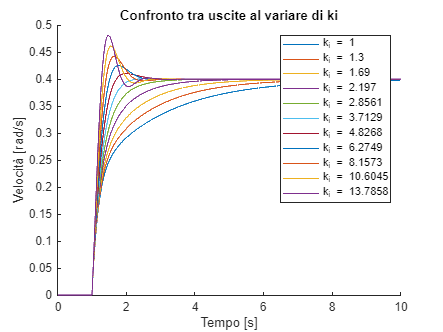

%imposto un flag per eseguire la ricerca di ki o non eseguirle per una
%volta che è stato già trovato
esegui_ricerca_flag = true;

if esegui_ricerca_flag
    
    %specifiche desiderate
    SovrMax = 0.2;
    
    ki = 1;
    ki_step = 1.3;        % moltiplico ki per ki_step
    max_iter = 20;        % Numero massimo di iterazioni
    iter = 0;
    
    % Inizializzazione array per salvare i risultati
    velocita_array = {}; 
    tempo_array = {};
    ki_array = {};
    
    
    % Inizializzazione
    sovraelongazione = -Inf;
    sovraelongazione_precedente = -Inf;
    ki_precedente = -1;
    
    
    % Inizio ciclo di ottimizzazione
    while sovraelongazione < SovrMax && iter < max_iter
        iter = iter + 1;
    
        % Simulazione
        out = run_simulation(Tsim);
    
        % Estrazione dei segnali
        velocita_array{iter} = out.w_sim.Data;
        tempo_array{iter} = out.w_sim.Time;
        ki_array{iter} = ki;
        
        
        %calcolo del picco e del regime
        max_vel = max(velocita_array{iter});
        regime = velocita_array{iter}(end);
        sovraelongazione = (max_vel - regime) /regime;
        
        
        % Stampa stato
        fprintf('Iterazione %d: Ki = %.2f, sovraelongazione = %.4f\n', iter, ki, sovraelongazione);
    
        % Aggiorno Ki
        if sovraelongazione < SovrMax 
            %salvo le variabili perché se al prossimo ciclo supererò SovrMax
            %saranno quelle valide
            ki_precedente = ki;
            sovraelongazione_precedente = sovraelongazione;
            
            %aggiornamento
            ki = ki * ki_step;     
        end
    end
    
    %sono andato oltre SovrMax%, prendo le precedenti
    ki = ki_precedente;
    sovraelongazione = sovraelongazione_precedente;
    
    
    %plot del procedimento
    N = numel(velocita_array);  % Numero di plot
    
    figure;
    hold on
    for i = 1:N
        plot(tempo_array{i}, velocita_array{i}, 'DisplayName', ['k_i = ' num2str(ki_array{i})]);
    end
    xlabel('Tempo [s]');
    ylabel('Velocità [rad/s]');
    title('Confronto tra uscite al variare di ki');
    legend;
    hold off;

    filename = fullfile(plot_folder, 'confrontoUsciteKi.png');
    saveas(gcf, filename);
    
else
    %ki già trovato da una precedente simulazione
    ki = 10.60;
    sovraelongazione = 0.1534;
end



% Output finale
fprintf('\nValore finale di Ki: %.2f con sovrelongazione %.4f\n', ki, sovraelongazione );


Valore finale di Ki: 10.60 con sovrelongazione 0.1534


Il grafico delle risposte a gradino in funzione di ki ci mostra che** maggiore è k**i:

- Più alta è la sovraelongazione S%

- Più breve è il tempo di risposta Ta

Scegliendo Ki per una sovraelongazione < 20% abbiamo ottenuto il giusto trade-off.

 Si vede stavolta che il sistema **segue il riferimento,** mentre la corrente non va in saturazione.

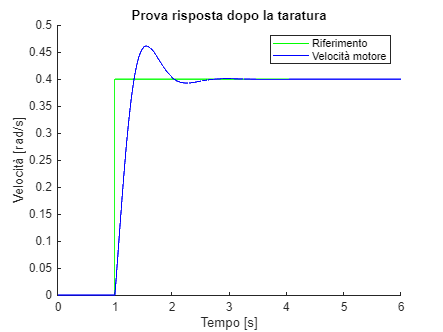

% Simulazione
Tsim = 6;
out = run_simulation(Tsim);

% Estrazione dei segnali
velocita = out.w_sim.Data;
tempo = out.w_sim.Time;
riferimento = squeeze(out.rif_sim.Data);
corrente = out.i_sim.Data;


% Plot dei risultati
figure;
hold on;
plot(tempo, riferimento, 'g', 'DisplayName', 'Riferimento' );
plot(tempo, velocita, 'b', 'DisplayName', 'Velocità motore');
xlabel('Tempo [s]');
ylabel('Velocità [rad/s]');
title('Prova risposta dopo la taratura');
legend('Location', 'northeast');
hold off;

filename = fullfile(plot_folder, 'rispostaGradinoDopoTaratura.png');
saveas(gcf, filename);

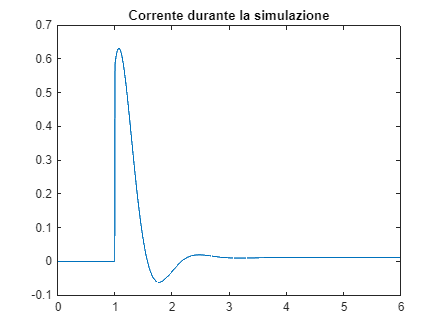


figure;
plot(tempo, corrente)
title('Corrente durante la simulazione');

### Saturazione del controllo, anti-wind-up

Immaginiamo di voler far generare il controllo dallo stesso **microcontrollore **usato per il riferimento e per la lettura della retroazione. 

Questo può generare il segnale di controllo solo in un **range limitato **[Gnd, HighVoltage], ovvero sarà saturato.

lv_alto_saturazione = High_voltage;
lv_basso_saturazione = Gnd;

Le simulazioni mostrano che **l'aggiunta del blocco di saturazione non degrada le prestazioni**, in quanto a saturare era già il blocco amplificatore.

Si manifesta però il fenomeno del **wind-up sul controllo**

Risolveremo il problema usando il seguente **schema anti-wind up **dove come anti-saturazione abbiamo semplicemente usato un guadagno già tarato manulmente nel simulink

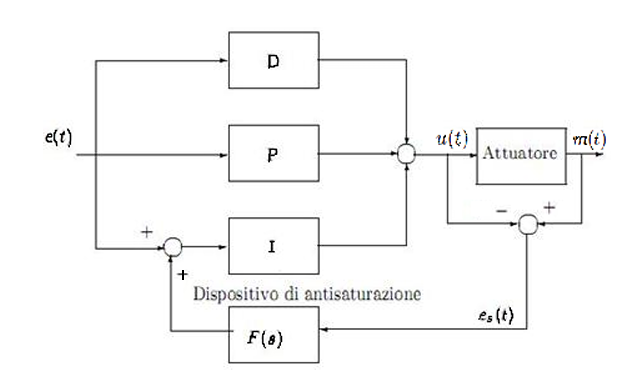

Simuliamo il circuito senza e con anti-wind up. Useremo come riferimento un gradino di ampiezza 3 e dinamo ideale.

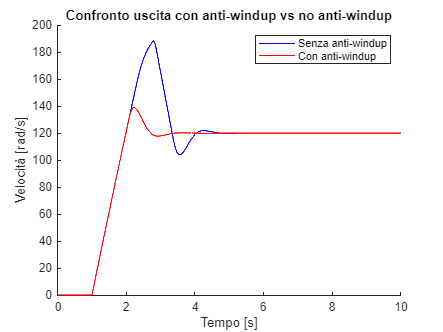

%setting Simulink
Tsim = 10;
set_input_sim(3, 0, genera_segnale_nullo(dt, Tsim), false, lv_alto_saturazione, lv_basso_saturazione, false, 0, 0); 
    %nota: qui anti wind-up è stato settato a false, ma lo setteremo nel
    %ciclo for propriamente, una volta false e una volta true
    

% Definizione parametri per il ciclo for
parametri = {
    false;  % senza anti-windup
    true;   % con anti-windup
};

% Inizializzazione array per salvare i risultati
velocita_array = {}; 
tempo_array = {};
controllo_no_sat_array = {};
controllo_sat_array = {};

for i = 1:length(parametri)
    anti_wind_up = parametri{i};

    % Simulazione
    out = run_simulation(Tsim);

    % Estrazione dei segnali
    velocita_array{i} = out.w_sim.Data;
    controllo_no_sat_array{i} = out.controllo_no_sat.Data;
    controllo_sat_array{i} = out.controllo_sat.Data;
    tempo_array{i} = out.w_sim.Time;
end

% Plot dei risultati in velocità
figure;
hold on;
plot(tempo_array{1}, velocita_array{1}, 'b', 'DisplayName', 'Senza anti-windup');
plot(tempo_array{2}, velocita_array{2}, 'r', 'DisplayName', 'Con anti-windup');
xlabel('Tempo [s]');
ylabel('Velocità [rad/s]');
title('Confronto uscita con anti-windup vs no anti-windup');
legend;
hold off;

filename = fullfile(plot_folder, 'uscitaConfrontoWindUp.png');
saveas(gcf, filename);

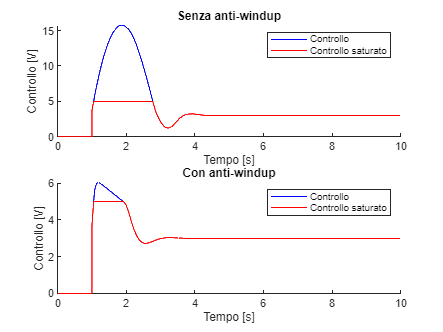


% Plot dei risultati sul controllo
figure;

subplot(2, 1, 1);
hold on;
plot(tempo_array{1}, controllo_no_sat_array{1}, 'b', 'DisplayName', 'Controllo');
plot(tempo_array{1}, controllo_sat_array{1}, 'r', 'DisplayName', 'Controllo saturato');
title('Senza anti-windup');
xlabel('Tempo [s]');
ylabel('Controllo [V]');
legend;
hold off;

subplot(2, 1, 2);
hold on;
plot(tempo_array{2}, controllo_no_sat_array{2}, 'b', 'DisplayName', 'Controllo');
plot(tempo_array{2}, controllo_sat_array{2}, 'r', 'DisplayName', 'Controllo saturato');
title('Con anti-windup');
xlabel('Tempo [s]');
ylabel('Controllo [V]');
legend;
hold off;


filename = fullfile(plot_folder, 'controlloConfrontoWindUp.png');
saveas(gcf, filename);

Si osserva che compensando il fenomeno del wind-up, aumentano notevolmente le prestazioni a ciclo chiuso:

- **diminuzione della sovraelongazione**

- **diminuzione del tempo di assestamento**

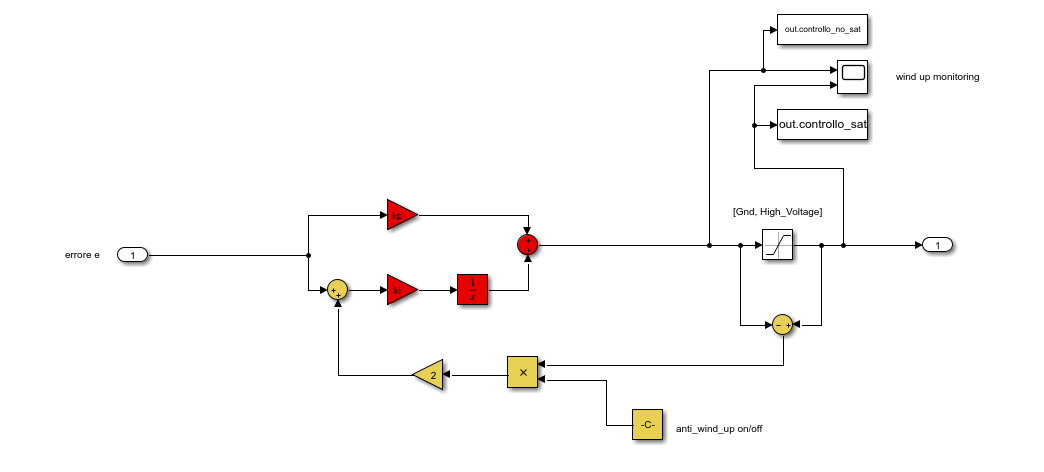

### Feedforward

Introducendo la parte integrativa è stato garantito l'astatismo a gradino. Dalla teoria dei sistemi, sappiamo che un sistema di questo tipo **segue la rampa con errore finito a regime**.

Per inseguire la rampa, introduciamo sul controllo l'azione di** feedforward**

kff = kv / (kamp * kdt * k_deamp)       %dalla teoria

kff = 0.9771

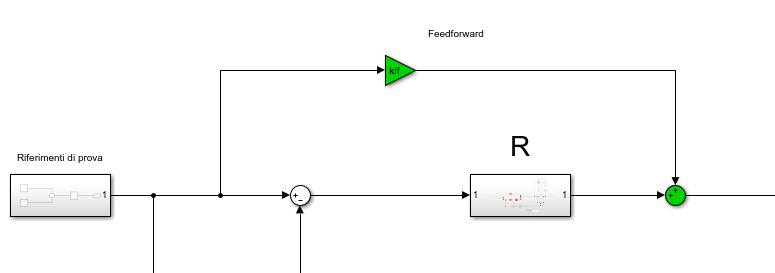

Eseguiamo una simulazione in **risposta a rampa**.

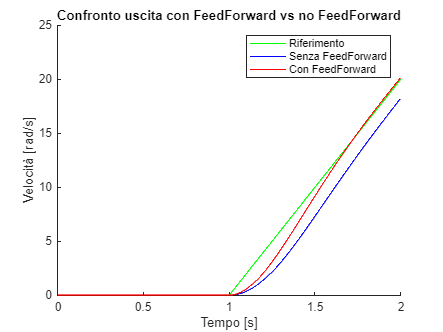

% Input sim
Tsim = 2;
set_input_sim(0, 0.5, genera_segnale_nullo(dt, Tsim), false, lv_alto_saturazione, lv_basso_saturazione, true, 0, 0); 
    %Nota: kff è stato settato a 0, ma sarà propriamente settato nel ciclo
   

% Definizione parametri per il ciclo for
parametri = {
    0;                             % senza feedforward
    kv / (kamp * kdt * k_deamp);   % con feedforward
};

% Inizializzazione array per salvare i risultati
velocita_array = {}; 
tempo_array = {};


for i = 1:length(parametri)
    kff = parametri{i};

    % Simulazione
    out = run_simulation(Tsim);

    % Estrazione dei segnali
    velocita_array{i} = out.w_sim.Data;
    tempo_array{i} = out.w_sim.Time;
    riferimento = squeeze(out.rif_sim.Data);
end


% Plot dei risultati
figure;
hold on;
plot(tempo_array{2}, riferimento, 'g', 'DisplayName', 'Riferimento' );
plot(tempo_array{1}, velocita_array{1}, 'b', 'DisplayName', 'Senza FeedForward');
plot(tempo_array{2}, velocita_array{2}, 'r', 'DisplayName', 'Con FeedForward');
xlabel('Tempo [s]');
ylabel('Velocità [rad/s]');
title('Confronto uscita con FeedForward vs no FeedForward');
legend;
hold off;


filename = fullfile(plot_folder, 'rispostaRampaFF.png');
saveas(gcf, filename);

### Asservimento in posizione

In questa applicazione non faremo asservimento in posizione, dato che l'unica uscita rilevante è la velocità. 

**Nota teorica: **In realtà può essere importante per rendere il motore ancora più preciso: pur non essendoci il bisogno di inseguire un riferimento in posizione, se lo fa è un indice di qualità.

### **Coppia di carico**

Fin'ora abbiamo tenuto il nostro motore a vuoto, ovvero senza carico (eccetto la struttura meccanica, la cui inerzia però è stata inglobata in quella del motore). Modelliamo la presenza di una persona sul nastro con una coppia di carico.

In prima approssimazione, la coppia resistente che viene generata è quella d'attrito tra il tappeto e il rullo.

m_carico = 120;
mu = 0.05;                % coeff attrito (ipotesi)
F_attr = m_carico * 9.8 * mu;
momento_attrito = F_attr * r_rotazionale

momento_attrito = 1.4700

Vediamo la risposta del sistema a gradino + rampa, con e senza il disturbo.

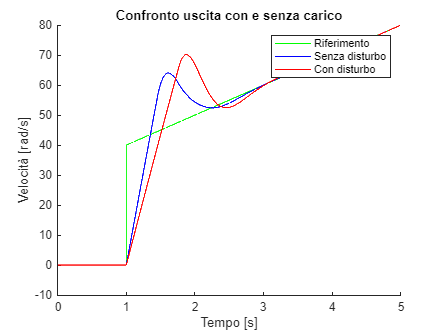

%Input simulink
Tsim = 5;
set_input_sim(1, 0.25, genera_segnale_nullo(dt, Tsim), false, lv_alto_saturazione, lv_basso_saturazione, true, kff, 0); 
    %Nota: Q carico è stato settato a 0, ma sarà propriamente settato nel ciclo


% Definizione parametri per il ciclo for
parametri = {
    0;                 % senza disturbo
    momento_attrito;   % con disturbo
};

% Inizializzazione array per salvare i risultati
velocita_array = {}; 
tempo_array = {};


for i = 1:length(parametri)
    coppia_carico = parametri{i};

    % Simulazione
    out = run_simulation(Tsim);

    % Estrazione dei segnali
    velocita_array{i} = out.w_sim.Data;
    tempo_array{i} = out.w_sim.Time;
    riferimento = squeeze(out.rif_sim.Data);
end


% Plot dei risultati
figure;
hold on;
plot(tempo_array{2}, riferimento, 'g', 'DisplayName', 'Riferimento' );
plot(tempo_array{1}, velocita_array{1}, 'b', 'DisplayName', 'Senza disturbo');
plot(tempo_array{2}, velocita_array{2}, 'r', 'DisplayName', 'Con disturbo');
xlabel('Tempo [s]');
ylabel('Velocità [rad/s]');
title('Confronto uscita con e senza carico');
legend;
hold off;


filename = fullfile(plot_folder, 'rispostaCoppiaCarico.png');
saveas(gcf, filename);

Il motore insegue il riferimento, pur con un piccolo e inevitabile degrado delle prestazioni (più lento e più sovraelongato)

### Generazione dei moti / riferimenti

Quando un utilizzatore sceglie una data velocità di funzionamento del tapis roulant, è chiaro che non possiamo dare al sistema un riferimento a gradino, in quanto il tappeto avrebbe uno sbalzo improvviso. 

Il comfort d'utilizzo prevede che la velocità di regime si raggiunga dolcemente e senza brusche accelerazioni.

Genereremo pertanto dei **riferimenti di velocità da accelerazione a forma triangolare.**

Le scelte progettuali, su base empirica, saranno le seguenti:

- Il tempo di raggiungimento della velocità desiderata, sarà ottenuto da  T_nec : w_fin = delta_t_nec_max : w_max

- 1/2 di tale intervallo di tempo sarà dedicato alla salita dell'accelerazione e 1/2 alla discesa

Con tale forma geometrica prevista per a_max, essendo la velocità finale (o comunque la variazione di velocità richiesta) l'integrale dell'accelerazione, si può trovara banalmente che:

        $wf = \frac{1}{2} T_{nec}a_{max}$      da cui..        $a_{max} = \frac{2w_{fin}}{T_{nec}$

Simuliamo una partenza da fermi fino ad una velocità di v_fin_km a scelta dall'utente

(NOTA: si è scelgo un algoritmo di generazione trapezoidale per generalità, poi specializzato a triangolare impostando tratto costante = 0)

%input
v_fin_km_h = 12                    %km/h

v_fin_km_h = 12

w_fin = (v_fin_km_h/3.6)/r_rotazionale     %rad_s

w_fin = 133.3333


% Parametri
T_nec = delta_t_acc_max * w_fin /w_max_rad_s

T_nec = 5.3333

a_max = 2 * w_fin / T_nec;
t_ramp = T_nec/2

t_ramp = 2.6667

t_acc_const = 0

t_acc_const = 0

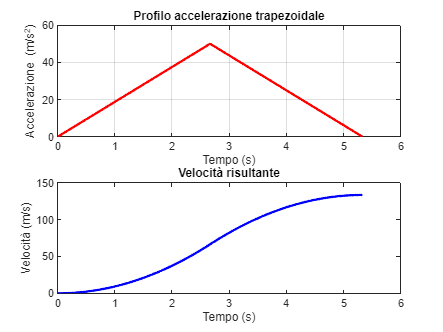



% Vettore tempo
%dt = 0.01;          
t = 0:dt:T_nec;

% Inizializzo vettori accelerazione e velocità
a = zeros(size(t));
v = zeros(size(t));

% Definizione accelerazione trapezoidale

% Fase 1: accelerazione crescente linearmente da 0 a a_max
idx1 = t <= t_ramp;
a(idx1) = (a_max/t_ramp)*t(idx1);

% Fase 2: accelerazione costante a_max
idx2 = t > t_ramp & t <= t_ramp + t_acc_const;
a(idx2) = a_max;

% Fase 3: accelerazione decrescente linearmente da a_max a 0
idx3 = t > t_ramp + t_acc_const;
a(idx3) = a_max - (a_max/t_ramp)*(t(idx3) - t_ramp - t_acc_const);

% Calcolo velocità integrando l'accelerazione
for i = 2:length(t)
    v(i) = v(i-1) + a(i-1)*dt;
end

% Plot accelerazione
figure;
subplot(2,1,1);
plot(t, a, 'r', 'LineWidth', 2);
xlabel('Tempo (s)');
ylabel('Accelerazione (m/s^2)');
title('Profilo accelerazione trapezoidale');
grid on;

% Plot velocità
subplot(2,1,2);
plot(t, v, 'b', 'LineWidth', 2);
xlabel('Tempo (s)');
ylabel('Velocità (m/s)');
title('Velocità risultante');

filename = fullfile(plot_folder, 'leggiMotoDaFermo.png');
saveas(gcf, filename);

Simuliamo la risposta a questo riferimento

Ovviamente il riferimento è in velocità, mentre noi stiamo lavorando coi riferimenti in tensione generati dal micro, quindi dovrà essere opportunamente scalato.

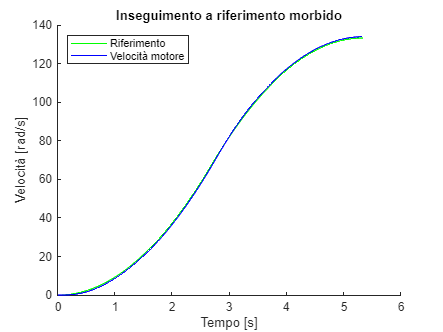


%input Simulink
Tsim = T_nec;

v_tensione = v / w_max_rad_s * High_voltage;            %mappatura su [Gnd, High_Voltage]
riferimento_generato = timeseries(v_tensione, t);       %riferimento morbido

set_input_sim(0, 0, riferimento_generato, true, lv_alto_saturazione, lv_basso_saturazione, true, kff, 0); 
   
% Simulazione
out = run_simulation(Tsim);

% Estrazione dei segnali
velocita = out.w_sim.Data;
tempo = out.w_sim.Time;
riferimento = squeeze(out.rif_sim.Data);


% Plot dei risultati
figure;
hold on;
plot(tempo, riferimento, 'g', 'DisplayName', 'Riferimento' );
plot(tempo, velocita, 'b', 'DisplayName', 'Velocità motore');
xlabel('Tempo [s]');
ylabel('Velocità [rad/s]');
title('Inseguimento a riferimento morbido');
legend('Location', 'northwest');
hold off;


filename = fullfile(plot_folder, 'rispostaLeggiMoto.png');
%saveas(gcf, filename);

**Osservazione: **partendo da un certo w0, 'unica cosa che cambia rispetto all'esempio appena trattato è che l'integrale dell'accelerazione mi fornisce la variazione di velocità e non la velocità finale.

Dunque posso generalizzare le mie leggi del moto a qualsiasi situazione.

**Nota:** daremo per scontato che il microcontrollore sappia generare tali segnali di riferimento, in quanto ha tutte le informazioni a disposizione. In questo breakpoint ci siamo occupati di simularli semplicemente.

### **Funzioni locali**

%riferimento nullo
function sn = genera_segnale_nullo(dt_sim, T_sim)
    t = 0:dt_sim:T_sim;                             
    z = zeros(size(t));                      
    sn = timeseries(z, t);
end

%setta le variabili per il circuito Simulink "controllo_motore"
function set_input_sim(isa, irs, rg, ns, sh, sl, awup, ff, cc)  
    %isa = ampiezza step riferimento
    %irs = pendenza rampa riferimento
    %rg = riferimento generato
    %ns = attiva rumore dinamo (reale e non ideale se true)
    %sh e sl = livelli saturazione del controllo high e low
    %awup = attiva anti-windup
    %ff = costante di feedforward
    %cc = coppia di carico (disturbo a gradino)
    
   

    % riferimento
    assignin('base', 'input_step_amplitude', isa);
    assignin('base', 'input_ramp_slope', irs);
    assignin('base', 'riferimento_generato', rg);

   
    % dinamo
    assignin('base', 'noise_on', ns);


    %saturazione controllo e windup
    assignin('base', 'saturazione_contr_high', sh);
    assignin('base', 'saturazione_contr_low', sl);

    assignin('base', 'anti_wind_up', awup);
   

    %feedforward
    assignin('base', 'kff', ff);


    %coppia di carico
    assignin('base', 'coppia_carico', cc);

   
end


function out = run_simulation(Tsim) 

    %sim
    model = 'controllo_motore';
    load_system(model);
    set_param(model, 'StopTime', num2str(Tsim));
    out = sim(model);
    
end


### Studente:

Schettini Francesco (A18000485)

### Esame

Azionamenti ed Elettronica Industriale  - prof Rubino Luigi - aa. 2024-25

### Università

Università degli studi della Campania Luigi Vanvitelli

Laurea magistrale in Ingegneria Informatica  - ramo Automazione